生成仿真用的数据

[dataGenArgs] = dataGen(1);

执行外部解题程序，并读入程序的输出

system("..\build\x64-Release\main.exe");

Total Cost = 210389280 


[totCost, edgeStat, sortedEdgeStat, edgePile, transactionPassEdgeID, transactionMinPath] = readResult();

对结果进行可视化分析

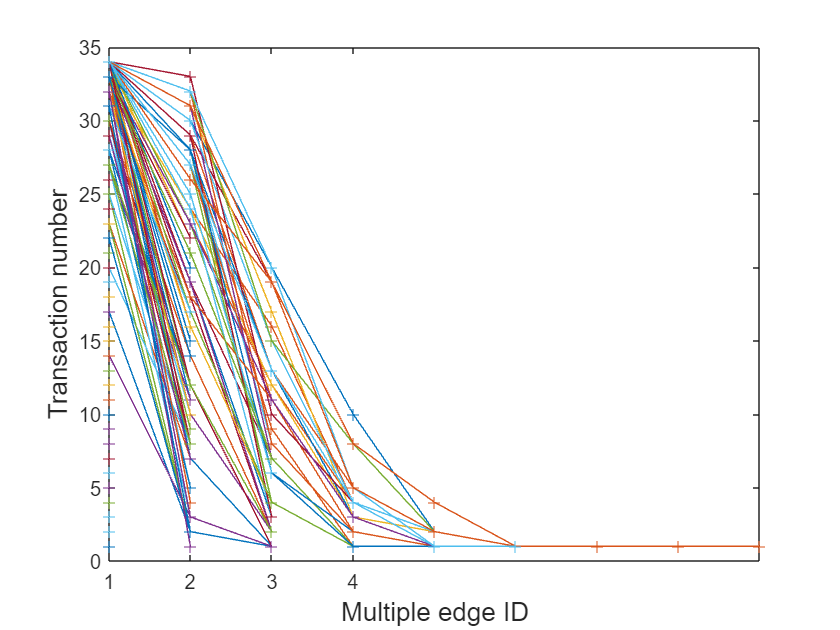

% [TransactionAllocation] = plotOverview(edgeStat);
[TranNumInMiltiEdge] = plotTranNumInMultiEdge(edgeStat);

transactionID = 499;
% plotUsedPilewithMinPath(transactionID, transactionMinPath, transactionPassEdgeID, edgeStat, edgePile);
% plotUsedPile3D(edgePile);

批量测试

% testTime = 1;
% costRecord = zeros(testTime, 6);
% for i = 1 : testTime
%     randomSeed = i;
%     [dataGenArgs] = dataGen(randomSeed);
%     costRecord(i, 1) = system("..\build\x64-Release\main.exe 0 0 0 0 0")
%     costRecord(i, 2) = system("..\build\x64-Release\main.exe 1 0 0 0 0")
%     costRecord(i, 3) = system("..\build\x64-Release\main.exe 1 1 0 0 0")
%     costRecord(i, 4) = system("..\build\x64-Release\main.exe 1 1 1 0 0")
%     costRecord(i, 5) = system("..\build\x64-Release\main.exe 1 1 1 1 0")
%     costRecord(i, 6) = system("..\build\x64-Release\main.exe 1 1 1 1 1")
% end
% plot(costRecord)